## **Relatório Matemática Computacional**

close all
clear all
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(-1)*(x-1).*((x+1).*exp(x)-2*exp(1));
d2f = @(x) (x.^2+2.*x-1).*exp(x-1)-2;
J = [0,3/2];

### **a)**

a = 1/10;
I = [0,0.7];

Para provar a convergência do método de Newton as condições do critério 1 têm de ser verificadas.

Sendo f uma função C^2

1) f(a)f(b)<0 (existência de raíz)

f(I(1),a).*f(I(2),a) < 0

ans = logical
   1


2) f'(x)!=0 para qualquer x pertencente ao intervalo I (unicidade da raíz)

d1f(I(1)).*d1f(I(2)) > 0

ans = logical
   1


(x.^2+2.*x-1).*exp(x-1)-2 < 0 para qualquer x pertencente ao intervalo I

3) f''(x)>=0 ou f''(x)<=0 para qualquer x pertencente ao intervalo I (não muda o sentido da concavidade)

(x.^2+2.*x-1).*exp(x-1)-2 < 0 para qualquer x pertencente ao intervalo I

4)

abs(f(I(1),a))./abs(d1f(I(1))) < I(2)-I(1)

ans = logical
   1


abs(f(I(2),a))./abs(d1f(I(2))) < I(2)-I(1)

ans = logical
   1


### b)

format LongE
r = real_zero(1/10,0.3);
fprintf('O zero real é: %i',r)

O zero real é: 4.970199e-01

[rbar,k] = newton_method(a,0.3,25, 10.^(-2));
fprintf("A raíz é: %i\n",rbar(end))

A raíz é: 4.970077e-01


fprintf("A iteração é: %i",k)

A iteração é: 3

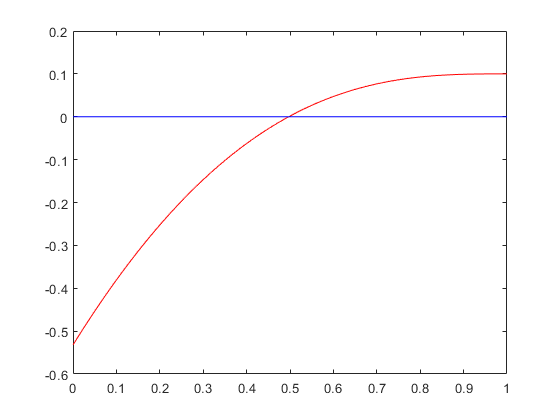


%Representação gráfica
s=0:0.01:1;
plot(s,((s-1).^2).*(exp(s-1)-1)+a,"Color",'r')
hold on
yy=zeros(1,length(s));
plot(s,yy,'Color','b')
hold off

### c)

M=41;
a_i = linspace(-1/10,1/10,M);
ga = [];
kga = [];
for i = 1:1:numberofelements(a_i)
    [rbar,k] = newton_method(a_i(i),0.9,25,10.^(-7));
    ga(end+1) = rbar(end);
    kga(end+1) = k;
end

#### i)

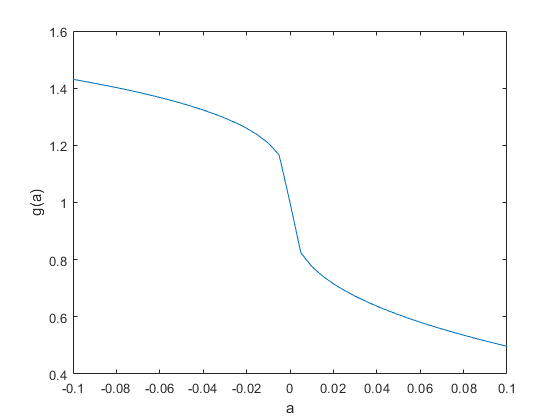

plot(a_i,ga)
xlabel('a')
ylabel('g(a)')

#### ii)

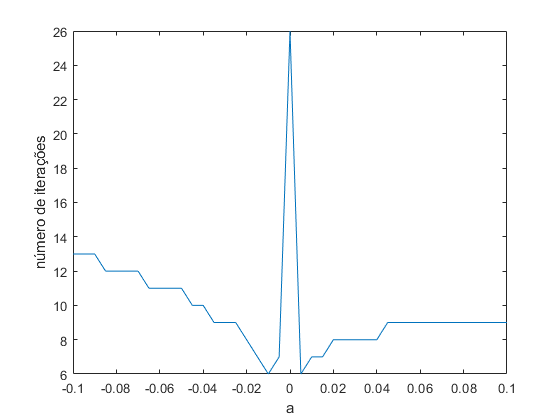

plot(a_i,kga)
xlabel('a')
ylabel('número de iterações')

fazer tabela

format short
[~,k1] = newton_method(-0.1,0.9,25,10.^(-7));
[~,k2] = newton_method(-0.05,0.9,25,10.^(-7));
[~,k3] = newton_method(0,0.9,25,10.^(-7));
[~,k4] = newton_method(0.05,0.9,25,10.^(-7));
[~,k5] = newton_method(0.1,0.9,25,10.^(-7));
[-0.01 -0.05 0 0.05 0.01; k1 k2 k3 k4 k5]

ans =    -0.0100   -0.0500         0    0.0500    0.0100
   13.0000   11.0000   26.0000    9.0000    9.0000


### d)

Através da visualização gráfica verificamos que para um determinado *a* a função f(a) tem um zero múltiplo.

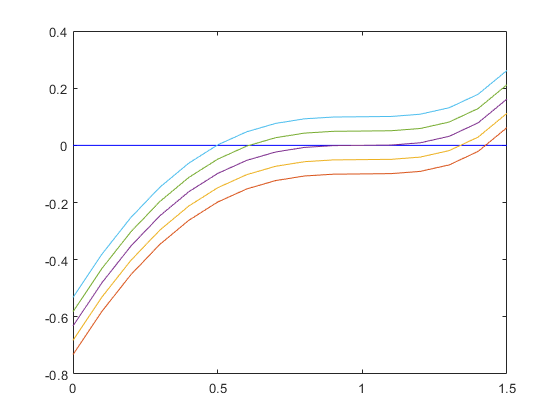

x = J(1):0.1:J(2);
yy=zeros(1,length(x));
plot(x,yy,'Color','b')
hold on
for  i = -1/10:0.05:1/10
    plot(x,f(x,i))
    %pause(0.5)
end
hold off

O zero múltiplo dá-se no caso em que no zero da função a sua respetiva derivada também é zero. Isso acontece quando a = 0 

Pelo gráfico apresentado na alínea anterior percebemos que o Método de Newton não funciona tão bem para estes casos uma vez que se destaca um pico no número de iterações em a = 0.

### e)

#### Caso a = 1/10, dada uma iterada x0

format long
a = 1/10;
x0 = 0.3;
k = 6;

r = real_zero(a,x0)

r =    0.497019917993889



%iteradas (k)
res = [x0];
for i = 1:1:k
    [v,~] = newton_method(a,x0,i,10.^(-7));
    res = [res, v(end)];
end
res

res =    0.300000000000000   0.454701044664434   0.494312438154520   0.497007663729377   0.497019917741053   0.497019917993889   0.497019917993889



%erros
erro = [];
for i = 1:1:k+1
    erro = [erro, r-res(i)];
end
erro

erro =    0.197019917993889   0.042318873329456   0.002707479839369   0.000012254264512   0.000000000252837  -0.000000000000000  -0.000000000000000


Experimentar convergência linear p = 1:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^1];
end
K

K =    0.214794898710536   0.063978069980527   0.004526077843352   0.000020632547614   0.000000219553380   1.000000000000000


Como K tende para 0 podemos concluir que a ordem de convergência é  p>1 e por isso supralinear.

Experimentar convergência quadrática p = 2:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^2];
end
K

K = 	1.0e+16 *

   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000087   1.801439850948198


Neste caso K tende para infinito logo nada se conclui.

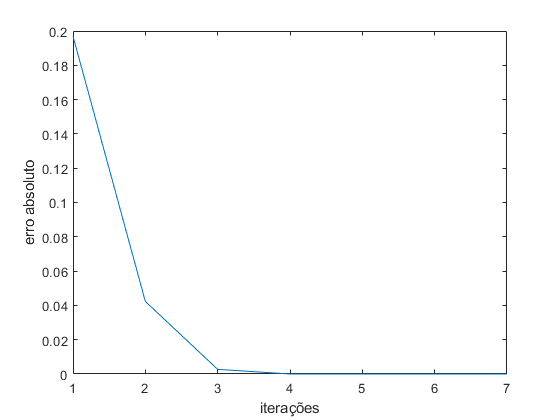

%Desenhar gráfico do erro absoluto em função das iterações
x = 1:1:k+1;
plot(x,erro)
xlabel('iterações')
ylabel('erro absoluto')

#### Caso a = 0, dada uma iteração x0

a = 0;
x0 = 0.3;
k = 10;

r = real_zero(a,x0)

r =      1



%iteradas (k)
res = [x0];
for i = 1:1:k
    [v,~] = newton_method(a,x0,i,10.^(-7));
    res = [res, v(end)];
end
res

res =    0.300000000000000   0.560174330486048   0.717470873509472   0.816071853050953   0.879258869826157   0.920315495011558   0.947229690823825   0.964974487737426   0.976717810969820   0.984508654654969   0.989685768668824



%erros
erro = [];
for i = 1:1:k+1
    erro = [erro, r-res(i)];
end
erro

erro =    0.700000000000000   0.439825669513952   0.282529126490528   0.183928146949047   0.120741130173843   0.079684504988442   0.052770309176175   0.035025512262574   0.023282189030180   0.015491345345031   0.010314231331176


Experimentar convergência linear p = 1:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^1];
end
K

K =    0.628322385019931   0.642366160216954   0.651005966123684   0.656458145078206   0.659961563004355   0.662240534515831   0.663735210374466   0.664720871336329   0.665373231226275   0.665806042112704


Como K tende para uma constante positiva <1 quando o número de iteradas vai para infinito, a ordem de convergência é p=1, isto é linear. Isto acontece no caso especial em que f'(z) = 0.

Experimentar convergência quadrática p = 2:

%Descobrir coeficiente assintótico de convergência, K
K = [];
for i = 1:1:k
    K = [K, abs(erro(i+1))/(abs(erro(i))).^2];
end
K

K =    0.897603407171330   1.460501750447690   2.304208327864237   3.569101064558994   5.465921695897197   8.310781808983950  12.577815456008977  18.978191278207362  28.578637101682546  42.979226612248155


Neste caso K tende para infinito logo nada se conclui.

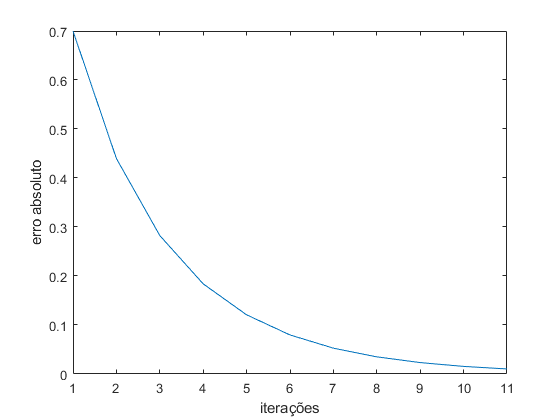

%Desenhar gráfico do erro absoluto em função das iterações
x = 1:1:k+1;
plot(x,erro)
xlabel('iterações')
ylabel('erro absoluto')

### f)

*Preciso ter um resultado em e) para dizer alguma coisa*

### Definição de Funções

%Função do Método de Newton
function [rbar,k] = newton_method(a,x0,nmax,epsilon)
nmax = nmax+1;
f = @(x,a) ((x-1).^2).*(exp(x-1)-1)+a;
d1f = @(x) exp(-1)*(x-1).*((x+1).*exp(x)-2*exp(1));
x=[x0];
k=1;
while k<nmax
    x(k+1)= x(k)-f(x(k),a)./d1f(x(k));
    if abs(x(k+1)-x(k)) < epsilon;
        break
    end
    k=k+1;
end
rbar = x;
end

%Função do zero real
function [r] = real_zero(a,x0)
g = @(x)((x-1).^2).*(exp(x-1)-1)+a;
r = fzero(g,x0);
end